# UWB Ranging Using IEEE 802.15.4z

This example shows how to estimate distance between two devices as per the IEEE® 802.15.4z™ standard [ 2 ] by using features in the Communications Toolbox™. 

## Overview

The IEEE 802.15.4z amendment [ 2 ] of the IEEE® 802.15.4 standard [ 1 ] specifies the MAC and PHY layers, and associated ranging and localization using ultra wideband (UWB) communication. The very short pulse durations of UWB allow a finer granularity in the time domain and therefore more accurate estimates in the spatial domain. 

The key ranging and localization functionality of the 802.15.4z amendment includes three MAC-level techniques:

- Single-sided two-way ranging (SS-TWR) - One device estimates the distance between two devices by using frame transmission in both directions of a wireless 802.15.4z link.

- Double-sided two-way ranging (DS-TWR) - Both devices estimate the distance between the two devices by using frame transmission in both directions of a wireless 802.15.4z link.

- One-way ranging / time-difference of arrival (OWR/TDOA) - Network-assisted localization whereby one device communicates with a set of synchronized nodes to estimate the position of the device. This technique is demonstrated in the [UWB Localization using IEEE 802.15.4z](docid:comm_ug#example-UWBLocalization) example.

This example demonstrates the SS-TWR technique by using PHY frames that are compatible with the IEEE 802.15.4 standard [ 1 ] and the IEEE 802.15.4z amendment [ 2 ]. For more information on generating PHY-level IEEE 802.15.4z waveforms, see the [HRP UWB IEEE 802.15.4a/z Waveform Generation](docid:comm_ug#example-HRPUWBWaveformGenerationExample) example.

## Single-Sided Two-Way Ranging (SS-TWR)

Two-way ranging involves frame transmission in both directions of a wireless 802.15.4z link. Single-sided ranging means that only one of the two devices estimates the distance between them. 

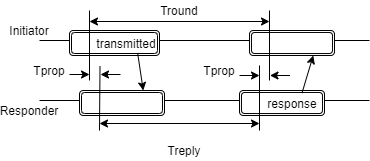

Each frame is timed at its ranging marker (RMARKER), which is the time of the first symbol following the start-of-frame delimiter (SFD). For more information on the fields in the transmitted frame, see the [HRP UWB IEEE 802.15.4a/z Waveform Generation](docid:comm_ug#example-HRPUWBWaveformGenerationExample) example. The ranging responder device, transmits the response frame after a certain reply time (Treply). The ranging initiator device computes the round-trip time (Tround) as the time-distance between the RMARKERs of the transmitted and the response frames. Treply is communicated from the ranging responder device to the ranging initiator device, so that the latter estimates the propagation time (Tprop) as Tprop = (Tround - Treply)/2.

The IEEE 802.15.4z amendment [ 2 ] specifies multiple possibilities for sharing Treply:

- Communication of Treply from the responder to the initiator is deferred, and performed with another message following the response frame.

- Embed Treply in the response frame.

- Set Treply to a fixed value known between the initiator and the responder.

This example considers the fixed reply time scenario between the two devices.

IEEE 802.15.4 [ 1 ] specifies that the exchanged frames must be a Data frame and its acknowledgement. The IEEE 802.15.4z amendment [ 2 ] relaxes this specification and allows the ranging measurement to be performed over any pair of transmitted and response frames. However, for the fixed reply time scenario, the 802.15.4z amendment specifies exchange of scrambled timestamp sequence packet configuration option three (SP3) frames. SP3 frames contain a scrambled timestamp sequence (STS) and no PHY header (PHR) or payload.

This example focuses on the basic ranging exchange without demonstrating the preceding set-up and following finish-up activities associated with the ranging procedure.

## Setup

Determine the actual distance and Tprop, and initialize visualizations. Configure a `timescope` object to plot the initiator and responder signals.

c = physconst('LightSpeed');    % Speed of light (m/s)
actualDistance = 5;             % In meters
actualTprop = actualDistance/c; % In seconds
SNR = 30;                       % Signal-to-Noise ratio
symbolrate = 499.2e6;           % Symbol rate for HRP PHY
sps = 10;                       % Samples per symbol
ts = timescope( ...
    SampleRate=sps*symbolrate, ...
    ChannelNames={'Initiator','Responder'}, ...
    LayoutDimensions=[2 1], ...
    Name='SS-TWR');
ts.YLimits = [-0.25 0.25];
ts.ActiveDisplay = 2;
ts.YLimits = [-0.25 0.25];

## Transmitted Frame

#### **Transmission from Initiator**

Generate the waveform containing SP3 PHY frames (with no MAC frame/PSDU) to be transmitted between the devices. Register the transmitted frame on the timeline of the initiator.

sp3Config = lrwpanHRPConfig( ...
    Mode='HPRF', ...
    STSPacketConfiguration=3, ...
    PSDULength=0, ...
    Ranging=true);
sp3Wave = lrwpanWaveformGenerator(zeros(0,1), sp3Config);
[transmitFrame,responseFrame] = deal(sp3Wave);

% start initiator time at the start of transmission
initiatorView = transmitFrame; 

#### Wireless Channel

Filter the transmission frame through an AWGN channel and add propagation delay. Then, update timeline for both link endpoints.

samplesToDelay = actualTprop*sp3Config.SampleRate;
receivedTransmitted = lclDelayWithNoise( ...
    transmitFrame,samplesToDelay,SNR);

initiatorView = [initiatorView; zeros(ceil(samplesToDelay),1)];
responderView = receivedTransmitted;

#### Reception at Responder

At the responder side, detect the preamble of the 802.15.4z PHY frame, and then process the transmitted frame. Preamble detection consists of determining the first instance of the preamble out of Nsync = PreambleDuration. Plot the initiator and responder views on a `timescope`.

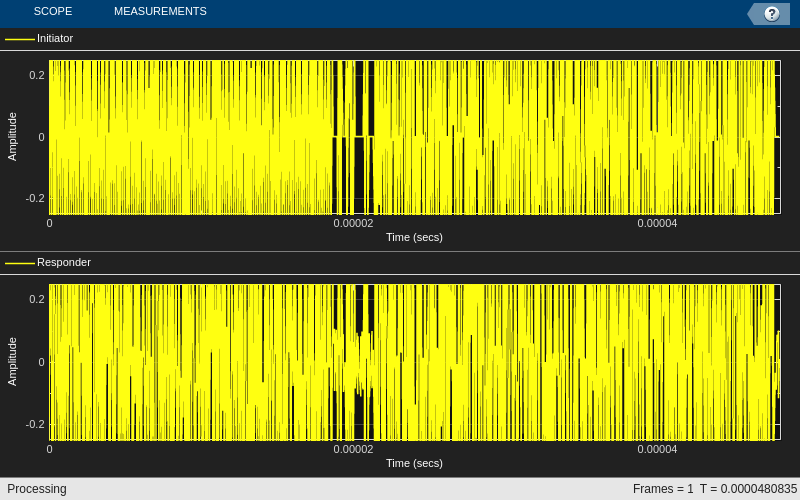

ind = lrwpanHRPFieldIndices(sp3Config); % length (start/end) of each field

sp3Preamble = sp3Wave(1:ind.SYNC(end)/sp3Config.PreambleDuration);
preamPos = helperFindFirstHRPPreamble( ...
    receivedTransmitted,sp3Preamble,sp3Config);

ts(initiatorView,responderView);

## Response Frame

#### Transmission from Responder

Set the Treply time to the length of three SP3 frames to specify when to transmit the response frame. Set the first and last RMARKER sample indices on the responder side to be the beginning of first post-SFD symbol and Treply samples later. After Treply samples, transmit the response frame from the responder device.

Treply = 3*length(sp3Wave); % in samples

% Find RMARKERs at responder side
frameStart = 1+preamPos-ind.SYNC(end)/sp3Config.PreambleDuration;
sfdEnd = frameStart + ind.SYNC(end) + diff(ind.SFD);
RMARKER_R1 = sfdEnd+1;                                    
RMARKER_R2 = RMARKER_R1 + Treply;

% Transmit after Treply. Find how long the responder needs 
% to remain idle.
idleResponderTime = Treply - diff(ind.STS)-1 - diff(ind.SHR)-1;
responderView = ...
    [responderView; zeros(idleResponderTime,1); ...
    responseFrame; zeros(ceil(samplesToDelay),1)];

initiatorView = [initiatorView; zeros(idleResponderTime,1)];

#### Wireless Channel

Filter the transmission frame through an AWGN channel and add propagation delay. Then, update timeline for both link endpoints.

receivedResponse = lclDelayWithNoise( ...
    responseFrame,samplesToDelay,SNR);
initiatorView = [initiatorView; receivedResponse];

#### Reception at Initiator

Back at the initiator side, detect the preamble of the 802.15.4z PHY frame, and then process the transmitted frame.

txFrameEnd = ind.STS(end);
preamPos = helperFindFirstHRPPreamble( ...
    initiatorView(txFrameEnd+1:end),sp3Preamble,sp3Config);

## Range Estimation

Estimate the propagation delay and the distance between two devices. Set the first and last RMARKER sample indices on the initiator side to be the start of transmission (which is known at t=0) and the beginning of first post-SFD symbol. Use the RMARKERs, Tround, and Tprop to estimate the distance between initiator and responder.

RMARKER_I1 = 1+ind.SFD(end);
frameStart = 1+preamPos-ind.SYNC(end)/sp3Config.PreambleDuration;
sfdEnd = txFrameEnd + frameStart + ind.SYNC(end) + diff(ind.SFD);
RMARKER_I2 = sfdEnd+1;

Tround = RMARKER_I2 - RMARKER_I1;                 % In samples
Tprop = (Tround-Treply)/(2*sp3Config.SampleRate); % In seconds
estimatedDistance = c*Tprop;                      % In meters

This `timescope` illustrates the frame exchange as in Fig. 6-47a in [ 2 ] with X-axis limit zoomed in to see the propagation delay between the transmitted and response frames.

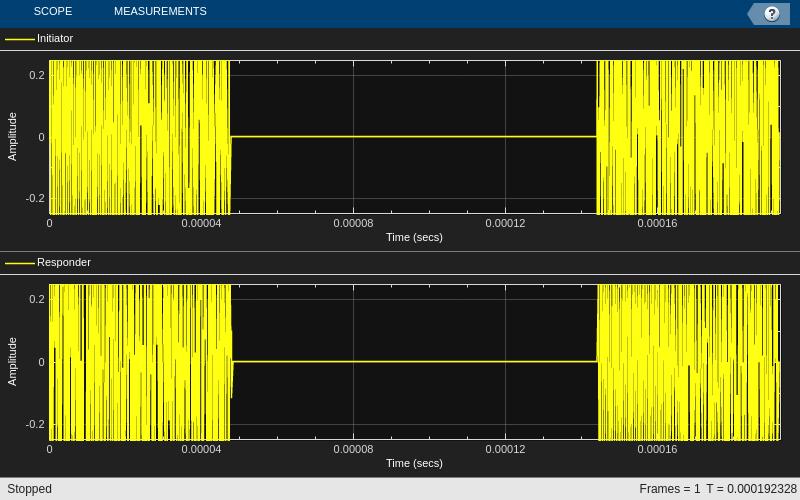

reset(ts);
ts([initiatorView; zeros(ceil(samplesToDelay),1)],responderView);
release(ts);

The estimated distance is a few centimeters different than the actual distance.

fprintf(['Actual distance = %d m.' ...
    '\nEstimated Distance = %0.2f m' ...
    '\nError = %0.3f m (%0.2f%%)\n'], ...
    actualDistance,estimatedDistance, ...
    estimatedDistance-actualDistance, ...
    100*(estimatedDistance-actualDistance)/actualDistance)

Actual distance = 5 m.
Estimated Distance = 5.03 m
Error = 0.030 m (0.59%)


For ranging methods that rely on estimating the time of flight (TOF), errors in the distance estimate are primarily caused when the propagation time (Tprop) is not an integer multiple of the sample time. The largest distance error for such ranging methods occurs when Tprop lasts half a sample time more than an integer multiple of sample time. The smallest distance error occurs when Tprop is an integer multiple of sample time. For the higher pulse repetition frequency (HRPF) mode of the high rate pulse repetition frequency (HRP) PHY used in this example, the symbol rate is 499.2 MHz and the number of samples per symbol is 10, which results in a maximum error in Tprop estimation of $0\ldotp 5\times c/\left(499\ldotp 2\times 10\right)$. So, the default ranging error lies between 0 and 3 cm.

In general, the larger channel bandwidth in UWB corresponds to shorter symbol duration and smaller ranging error as compared to narrowband communication. For the narrowband communication as specified in IEEE 802.11az, the channel bandwidth ranges from 20 MHz to 160 MHz. Considering the maximum Tprop error for narrowband communication, estimates for the ranging error lie between 0 and 10 cm for 160 MHz and between 0 and 75 cm for 20 MHz. For more information regarding ranging with IEEE 802.11az, see the [802.11az Positioning Using Super-Resolution Time of Arrival Estimation](docid:wlan_ug#example-HERangingPositioningExample) example.

## Further Exploration

This example uses these objects and functions from the Communications Toolbox™

- [`lrwpanHRPConfig`](docid:comm_ref#mw_838a7c27-eb97-42fe-bc8e-30a3c0de9f7f)**:** HRP waveform configuration

- [`lrwpanWaveformGenerator`](docid:comm_ref#mw_9127f1df-f8a2-4131-9dfa-a89604c1bb38)**:** Create an IEEE 802.15.4a/z HRP UWB waveform

function received = lclDelayWithNoise(transmitted, samplesToDelay, SNR)
% lclDelayWithNoise Operations of wireless channel (propagation delay, AWGN)

  vfd = dsp.VariableFractionalDelay;
  % zero pad @ end, to get entire frame out of VFD
  delayedTransmitted = vfd( ...
      [transmitted; zeros(ceil(samplesToDelay), 1)],samplesToDelay);
  % add white gaussian noise:
  received = awgn(delayedTransmitted,SNR);
end